syms m g l x1 x2 b s
I = m*l^2;

# Assignment 1

## Find transfer function from state space model

#### Set up matrices from state space model:

ident = [1 , 0 ; 0 , 1];
A = [0 , 1 ; cos(x1)*g/l , -b/I]

$$A = \left(\begin{array}{cc} 0 & 1\\ \frac{g\,\cos\left(x_{1}\right)}{l} & -\frac{b}{l^{2}\,m} \end{array}\right)$$

B = [0 ; 1/I]

$$B = \left(\begin{array}{c} 0\\ \frac{1}{l^{2}\,m} \end{array}\right)$$

C = [1 , 0];
D = 0;

#### Find symbolic transfer function:

inverse = inv(s*ident-A)

$$inverse = \begin{array}{l} \left(\begin{array}{cc} \frac{m\,s\,l^{2}+b}{\sigma_{1}} & \frac{l^{2}\,m}{\sigma_{1}}\\ \frac{g\,l\,m\,\cos\left(x_{1}\right)}{\sigma_{1}} & \frac{l^{2}\,m\,s}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m\,l^{2}\,s^{2}-g\,m\,\cos\left(x_{1}\right)\,l+b\,s \end{array}$$

C*inverse*B+D

$$ans = \frac{1}{m\,l^{2}\,s^{2}-g\,m\,\cos\left(x_{1}\right)\,l+b\,s}$$

#### Find numeric transfer function

A1 = [0 1 ; 9.82 -0.4];
B1 = [0 ; 4];
C1 = [1 , 0];
D1 = 0;
inverse1 = inv(s*ident-A1);
[b,a]=ss2tf(A1,B1,C1,D1)

b =      0     0     4


a =     1.0000    0.4000   -9.8200


sys = tf(b,a)

sys =
 
          4
  ------------------
  s^2 + 0.4 s - 9.82
 
Continuous-time transfer function.
Model Properties


pole(sys)

ans =    -3.3401
    2.9401


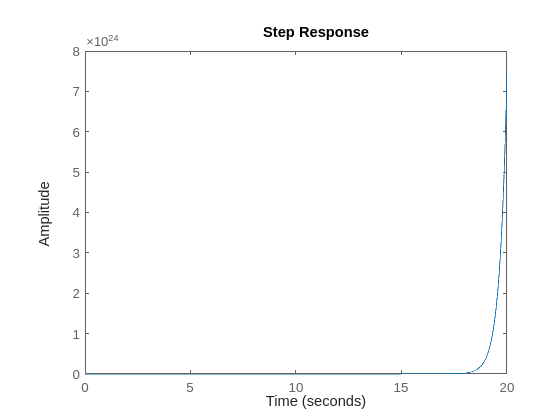

step(sys)

# P-controller

K_p = 2.46;
sysp = K_p*sys;
[r,k] = rlocus(sysp)

r = 1.0e+02 *

  -0.0334 + 0.0000i  -0.0302 + 0.0000i  -0.0299 + 0.0000i  -0.0295 + 0.0000i  -0.0292 + 0.0000i  -0.0288 + 0.0000i  -0.0284 + 0.0000i  -0.0279 + 0.0000i  -0.0274 + 0.0000i  -0.0269 + 0.0000i  -0.0262 + 0.0000i  -0.0255 + 0.0000i  -0.0247 + 0.0000i  -0.0239 + 0.0000i  -0.0229 + 0.0000i  -0.0217 + 0.0000i  -0.0204 + 0.0000i  -0.0189 + 0.0000i  -0.0170 + 0.0000i  -0.0147 + 0.0000i  -0.0116 + 0.0000i  -0.0061 + 0.0000i  -0.0030 + 0.0000i  -0.0020 + 0.0000i  -0.0020 + 0.0010i  -0.0020 + 0.0080i  -0.0020 + 0.0124i  -0.0020 + 0.0158i  -0.0020 + 0.0188i  -0.0020 + 0.0215i  -0.0020 + 0.0242i  -0.0020 + 0.0268i  -0.0020 + 0.0293i  -0.0020 + 0.0319i  -0.0020 + 0.0344i  -0.0020 + 0.0370i  -0.0020 + 0.0395i  -0.0020 + 0.0422i  -0.0020 + 0.0448i  -0.0020 + 0.0476i  -0.0020 + 0.0503i  -0.0020 + 0.0532i  -0.0020 + 0.0561i  -0.0020 + 0.0591i  -0.0020 + 0.0622i  -0.0020 + 0.0654i  -0.0020 + 0.0687i  -0.0020 + 0.0721i  -0.0020 + 0.0757i  -0.0020 + 0.0793i
   0.0294 + 0.0000i   0.0262 + 0.0

k = 1.0e+03 *

         0    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0019    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0033    0.0036    0.0039    0.0042    0.0046    0.0049    0.0054    0.0058    0.0063    0.0068    0.0074


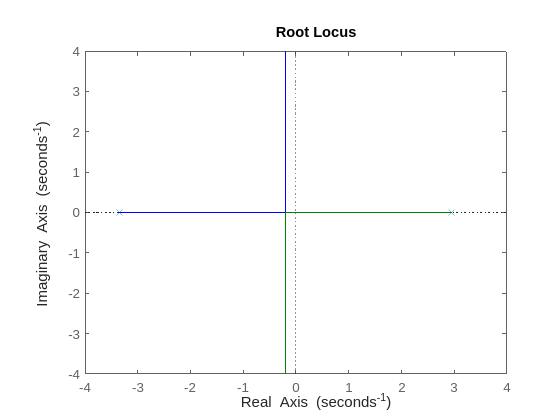

rlocus(sysp)

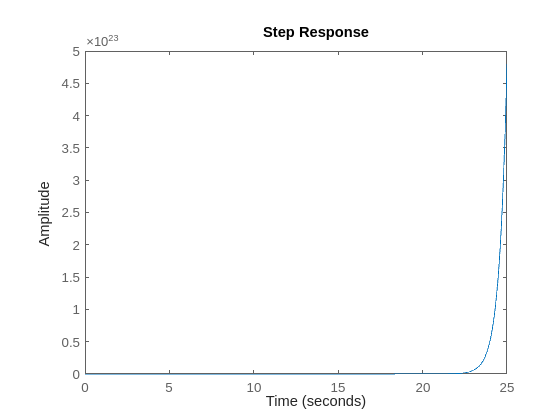

step(sys/(1+sys)) % Not useful

sysp = minreal(sysp/(1+sysp))

sysp =
 
         9.84
  ------------------
  s^2 + 0.4 s + 0.02
 
Continuous-time transfer function.
Model Properties


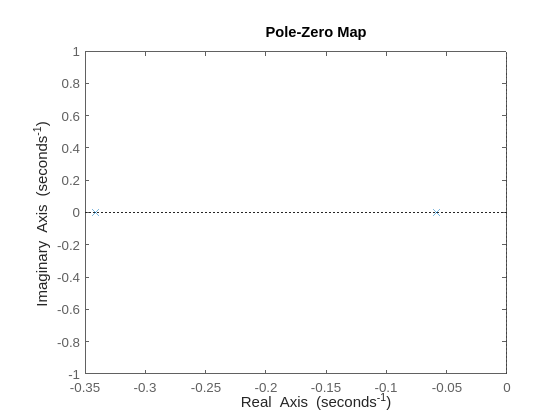

pzmap(sysp)

# PI-controller

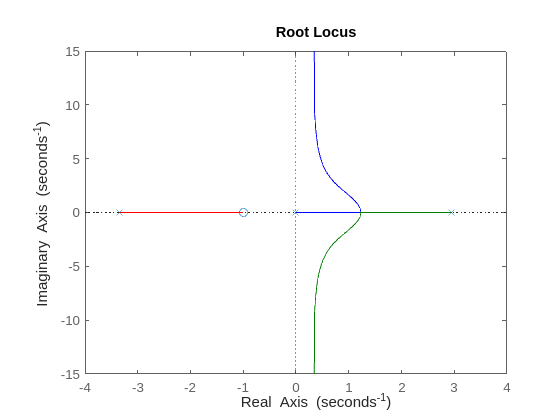

s = tf('s');
T_i = 1;
K_pi = K_p*(1+1/(T_i*s));
syspi = K_pi * sys;
rlocus(syspi) 

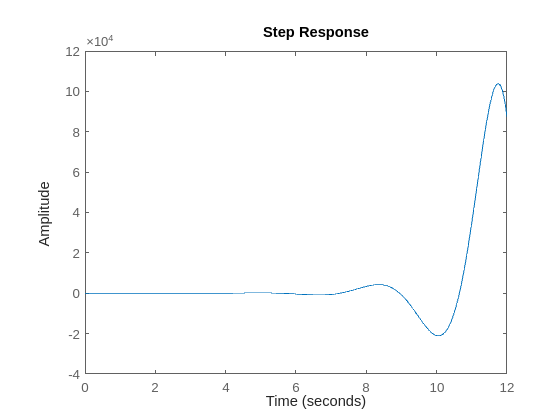

step(syspi/(1+syspi)) % Also not useful

# PD-controller

T_d = 1/2;
K_pd = K_p * (1 + T_d*s);
syspd = K_pd * sys % Open-loop system

syspd =
 
    4.92 s + 9.84
  ------------------
  s^2 + 0.4 s - 9.82
 
Continuous-time transfer function.
Model Properties


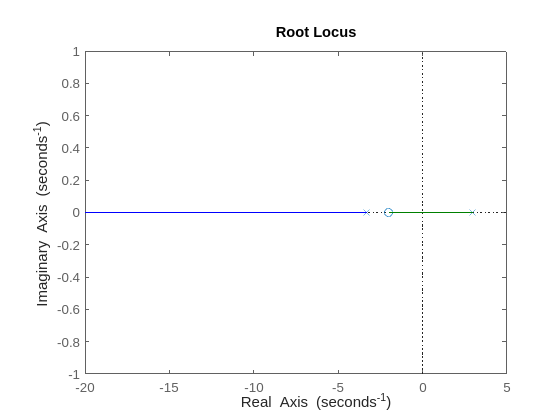

rlocus(syspd) % Looks promising

[poles, gains] = rlocus(syspd) % All poles have to be to the left of x = -1.8 according to performance specification.

poles =    -3.3401   -3.4226   -3.4312   -3.4406   -3.4511   -3.4628   -3.4758   -3.4903   -3.5064   -3.5244   -3.5446   -3.5672   -3.5925   -3.6211   -3.6533   -3.6897   -3.7311   -3.7780   -3.8317   -3.8931   -3.9636   -4.0450   -4.1391   -4.2485   -4.3760   -4.5250   -4.6997   -4.9047   -5.1455   -5.4281   -5.7591   -6.1452   -6.5936   -7.1112   -7.7052   -8.3826   -9.1503  -10.0159  -10.9871  -12.0724  -13.2811  -14.6236  -16.1112  -17.7567  -19.5744  -21.5798  -23.7903  -26.2253  -28.9059  -31.8555
    2.9401    2.6534    2.6256    2.5952    2.5619    2.5255    2.4857    2.4422    2.3946    2.3427    2.2860    2.2242    2.1569    2.0837    2.0041    1.9178    1.8243    1.7232    1.6142    1.4969    1.3713    1.2372    1.0947    0.9442    0.7862    0.6218    0.4522    0.2791    0.1046   -0.0689   -0.2389   -0.4030   -0.5589   -0.7048   -0.8397   -0.9628   -1.0742   -1.1741   -1.2634   -1.3428   -1.4132   -1.4756   -1.5309   -1.5799   -1.6233   -1.6619   -1.6962   -1.7267   -1.7540 

gains =          0    0.0751    0.0824    0.0905    0.0994    0.1092    0.1199    0.1317    0.1447    0.1589    0.1745    0.1917    0.2105    0.2312    0.2539    0.2789    0.3063    0.3364    0.3694    0.4057    0.4456    0.4894    0.5375    0.5903    0.6483    0.7120    0.7820    0.8589    0.9433    1.0360    1.1378    1.2496    1.3724    1.5073    1.6555    1.8182    1.9969    2.1931    2.4086    2.6454    2.9053    3.1909    3.5045    3.8489    4.2272    4.6426    5.0989    5.6000    6.1504    6.7548


index = 52; % That is true for the poles at this index
poles(:,index)

ans =  -700.4095
   -1.9905


gains(1,index) % those poles correspond to this open-loop gain. (kp = 351)

ans = 142.6829

G = gains(1,index)*(1+T_d*s); % Controller gain
sys1 = G*sys / (1+G*sys) % Transfer function of system with feedback

sys1 =
 
     285.4 s^3 + 684.9 s^2 - 2574 s - 5605
  -------------------------------------------
  s^4 + 286.2 s^3 + 665.4 s^2 - 2582 s - 5508
 
Continuous-time transfer function.
Model Properties


sys1 = minreal(sys1)

sys1 =
 
     285.4 s + 570.7
  ---------------------
  s^2 + 285.8 s + 560.9
 
Continuous-time transfer function.
Model Properties


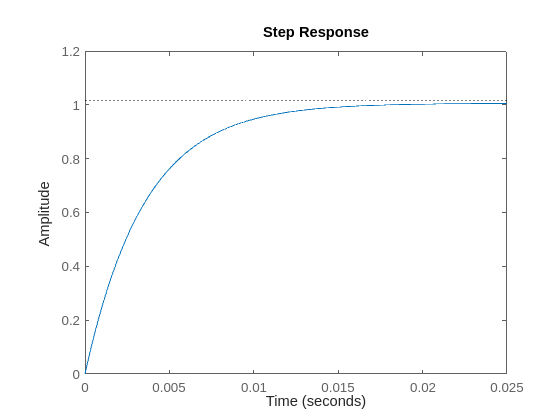

step(sys1)% Is compliant with our performance specification

pole(sys1)

ans =  -283.7893
   -1.9765


zero(sys1)

ans = -2.0000

stepinfo(sys1) % Info

ans = struct with fields:
         RiseTime: 0.0081
    TransientTime: 0.0167
     SettlingTime: 0.0167
      SettlingMin: 0.9181
      SettlingMax: 1.0076
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0076
         PeakTime: 0.0988


# PID-controller

Havent found a stable combination of parameters.

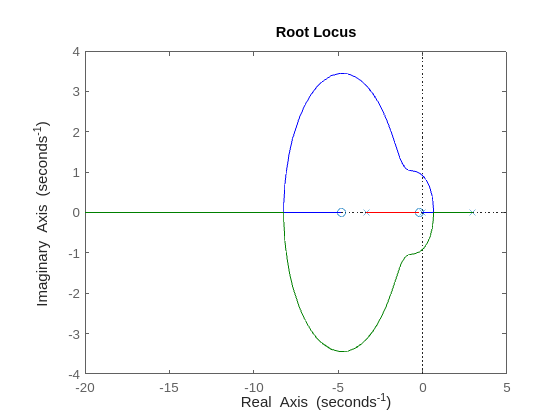

T_i = 5;
T_d = 1/5;
K_pid = K_p*(1+T_d*s+1/(T_i*s));
syspid = K_pid * sys;
rlocus(syspid)

[r,k] = rlocus(syspid)

r = 1.0e+02 *

   0.0000 + 0.0000i   0.0003 + 0.0000i   0.0003 + 0.0000i   0.0003 + 0.0000i   0.0004 + 0.0000i   0.0004 + 0.0000i   0.0005 + 0.0000i   0.0005 + 0.0000i   0.0006 + 0.0000i   0.0007 + 0.0000i   0.0008 + 0.0000i   0.0009 + 0.0000i   0.0011 + 0.0000i   0.0013 + 0.0000i   0.0016 + 0.0000i   0.0019 + 0.0000i   0.0025 + 0.0000i   0.0033 + 0.0000i   0.0060 + 0.0000i   0.0061 + 0.0000i   0.0065 + 0.0000i   0.0065 + 0.0004i   0.0061 + 0.0029i   0.0058 + 0.0036i   0.0056 + 0.0041i   0.0045 + 0.0058i   0.0039 + 0.0065i   0.0033 + 0.0071i   0.0019 + 0.0082i   0.0002 + 0.0091i  -0.0018 + 0.0098i  -0.0044 + 0.0102i  -0.0084 + 0.0105i  -0.0093 + 0.0107i  -0.0103 + 0.0111i  -0.0104 + 0.0111i  -0.0104 + 0.0111i  -0.0122 + 0.0123i  -0.0129 + 0.0129i  -0.0135 + 0.0136i  -0.0164 + 0.0172i  -0.0188 + 0.0202i  -0.0212 + 0.0229i  -0.0237 + 0.0253i  -0.0264 + 0.0274i  -0.0294 + 0.0294i  -0.0326 + 0.0311i  -0.0361 + 0.0325i  -0.0399 + 0.0336i  -0.0442 + 0.0343i
   0.0294 + 0.0000i   0.0264 + 0.0

k =          0    0.1150    0.1272    0.1408    0.1558    0.1725    0.1909    0.2113    0.2338    0.2588    0.2864    0.3170    0.3509    0.3883    0.4298    0.4756    0.5264    0.5826    0.6448    0.6453    0.6459    0.6466    0.6801    0.6969    0.7137    0.7899    0.8320    0.8742    0.9675    1.0708    1.1851    1.3116    1.4516    1.4763    1.5009    1.5024    1.5039    1.5553    1.5809    1.6066    1.7781    1.9680    2.1781    2.4106    2.6679    2.9528    3.2680    3.6169    4.0030    4.4304


r(:,70)

ans =    -5.3970
  -24.2285
   -0.2252


# Simulation of PD-controller

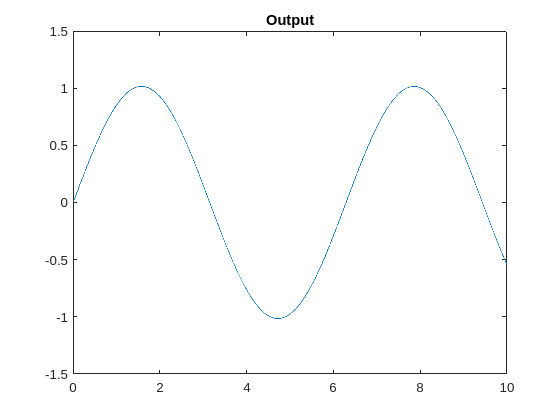

t = linspace(0,10,10000);
u = sin(t);

y = lsim(sys1,u,t);
plot(t,y)
hold on
title("Output")
hold off

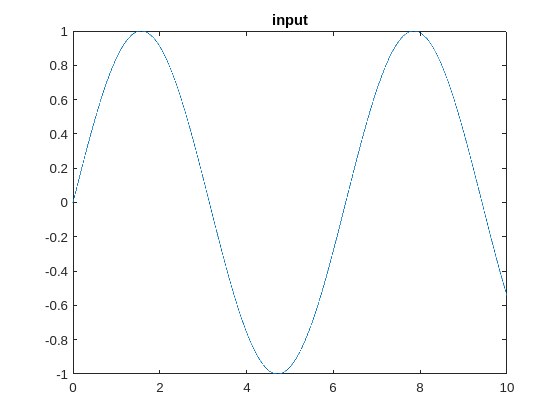

plot(t,u)
hold on
title("input")
hold off

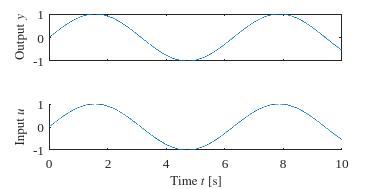

font_size=10;
width = 10;         
height = 5;
SCREEN_LEFT = 15;
SCREEN_RIGHT = 10;
ADD = 0;
figure
hold on
set(gcf,'Units','centimeters')
set(gcf,'Position',[SCREEN_LEFT  SCREEN_RIGHT  width+4*ADD  height+2*ADD])
set(gcf,'Color','w')
subplot(2,1,1)
hold on
plot(t,y)
set(gca,'FontName','Times New Roman','FontSize',font_size);
set(gca,'XTickLabel','');
ylabel('Output $y$','Interpreter','latex','FontSize',font_size)
box on
subplot(2,1,2)
hold on
plot(t,u)
set(gca,'FontName','Times New Roman','FontSize',font_size);
ylabel('Input $u$','Interpreter','latex','FontSize',font_size)
xlabel('Time $t$ [s]','Interpreter','latex','FontSize',font_size)


box on
box off